%clc
clear all
close all

## Parameters

Kernel = 'polynomial';
KernelScale = 1.7; 
Direction = 'backward';

## LOAD DATA

%addpath("/Users/lucagarello/Desktop/Dataset MAIA/Final Parameters");
addpath("/Users/lucagarello/Desktop/");
[Dataset] = load_dataset(0,'AT.csv','PT.csv'); %1 if you want to detect outliers
%[Dataset2] = load_dataset(0,'40NEG(jan).csv','40POS(jan).csv');
%Dataset = [Dataset ; Dataset2];

Dataset = find_outliers2(Dataset,'gesd',0); %'gesd'

ho trovato 2 outliers nel soggetto 5 della classe NEGATIVE 
ho trovato 11 outliers nel soggetto 7 della classe NEGATIVE 
ho trovato 1 outliers nel soggetto 12 della classe NEGATIVE 
ho trovato 3 outliers nel soggetto 16 della classe POSITIVE 




%Dataset(4,:) = [];
%Dataset(7-1,:) = [];
%Dataset(8-2,:) = [];
%Dataset(16-3,:) = [];
%Dataset(26-4,:) = [];
%Dataset(28-5,:) = [];



%Non modificare 40 settimane
% Dataset(7,:) = [];
% Dataset(16,:) = [];
% Dataset(26+30,:) = [];

Dataset(7,:) = [];
Dataset(15,:) = [];
%Dataset(16+12,:) = [];
writetable(Dataset,"AT-PT.csv")


%Dataset(5,:) = [];
%Dataset(6-1,:) = [];
%Dataset(8-2,:) = [];
%Dataset(1-1+28,:) = [];
%Dataset(5-4+28,:) = [];
%Dataset(7-5+28,:) = [];
%Dataset(22-2+28,:) = [];

% Dataset(5,:) = [];
% Dataset(6,:) = [];
% Dataset(8,:) = [];
% Dataset(1+28,:) = [];
% Dataset(5+28,:) = [];
% Dataset(7+28,:) = [];
% Dataset(22+28,:) = [];

%Dataset(7,:) = [];

## FEATURES SELECTION

Data = Dataset{:,1:end-1}; % Parameters
Labels = Dataset{:,end}; % Labels
% 
% mdl = fscnca(Data,Labels);
% figure()
% plot(mdl.FeatureWeights,'ro')
% grid on
% xlabel('Feature index')
% ylabel('Feature weight')
% 
% figure
% plot(mdl.FitInfo.Iteration,mdl.FitInfo.Objective,'ro-')
% grid on
% xlabel('Iteration Number')
% ylabel('Objective')

Sequential

%c = cvpartition(Labels,'Holdout',0.3); 
%partiziono dataset 0,3 e' il 30% del dataset come il testset
if false
    c = cvpartition(Labels,'LeaveOut');
    %c = cvpartition(Labels,'KFold',5);
    opts = statset('display','iter');
    
    classf = @(train_data,train_labels,test_data,test_labels) ...
            sum(predict(fitcsvm(train_data,train_labels,'KernelFunction', Kernel, ...
            'PolynomialOrder', [], ...
            'KernelScale', KernelScale, ... 
            'BoxConstraint', 1, ...
            'Standardize', true, 'ClassNames', categorical({'NEG'; 'POS'})), test_data) ~= test_labels); 
    [fs,history] = sequentialfs(classf,Data,Labels,'cv',c,'options',opts,'direction',Direction);
end

Dimensionality reduction

%fs = [1   0   0   0   0   1   0   1   0   0   1   0   0   0   0   0   0   0 ];
%40 
fs = [ 0   0   0   0   0   1   0   1   0   1   1   1   0   1   0   1   1   0 ]; % AT PT
fs = logical(fs);

fprintf('Sono state selezionate le features:');

Sono state selezionate le features:

Dataset(1,fs)

ans = 1×8 table
    JerkFeetCorrelation    skew_hands    Area_Nose    Area_Hands    Area_Feet    AreaStd_Hands    Periodicity_Nose    Periodicity_Hands
    ___________________    __________    _________    __________    _________    _____________    ________________    _________________

         0.057639            30.992       1.9263        33.557       21.879         6.8766            0.001985            0.0043287    



Dataset.Properties.VariableNames

ans = 1×19 cell array
    {'VelHandsCorrelation'}    {'AccHandsCorrelation'}    {'JerkHandsCorrelation'}    {'VelFeetCorrelation'}    {'AccFeetCorrelation'}    {'JerkFeetCorrelation'}    {'skew_Nose'}    {'skew_hands'}    {'skew_feet'}    {'Area_Nose'}    {'Area_Hands'}    {'Area_Feet'}    {'AreaStd_Nose'}    {'AreaStd_Hands'}    {'AreaStd_Feet'}    {'Periodicity_Nose'}    {'Periodicity_Hands'}    {'Periodicity_Feet'}    {'Labels'}


Dataset =  [ Dataset(:,fs) Labels]; 

## TRAINING

trainedClassifier = struct with fields:
    RequiredVariables: {30×1 cell}


Failed prediction of ITEM number 5
Failed prediction of ITEM number 14
Failed prediction of ITEM number 19


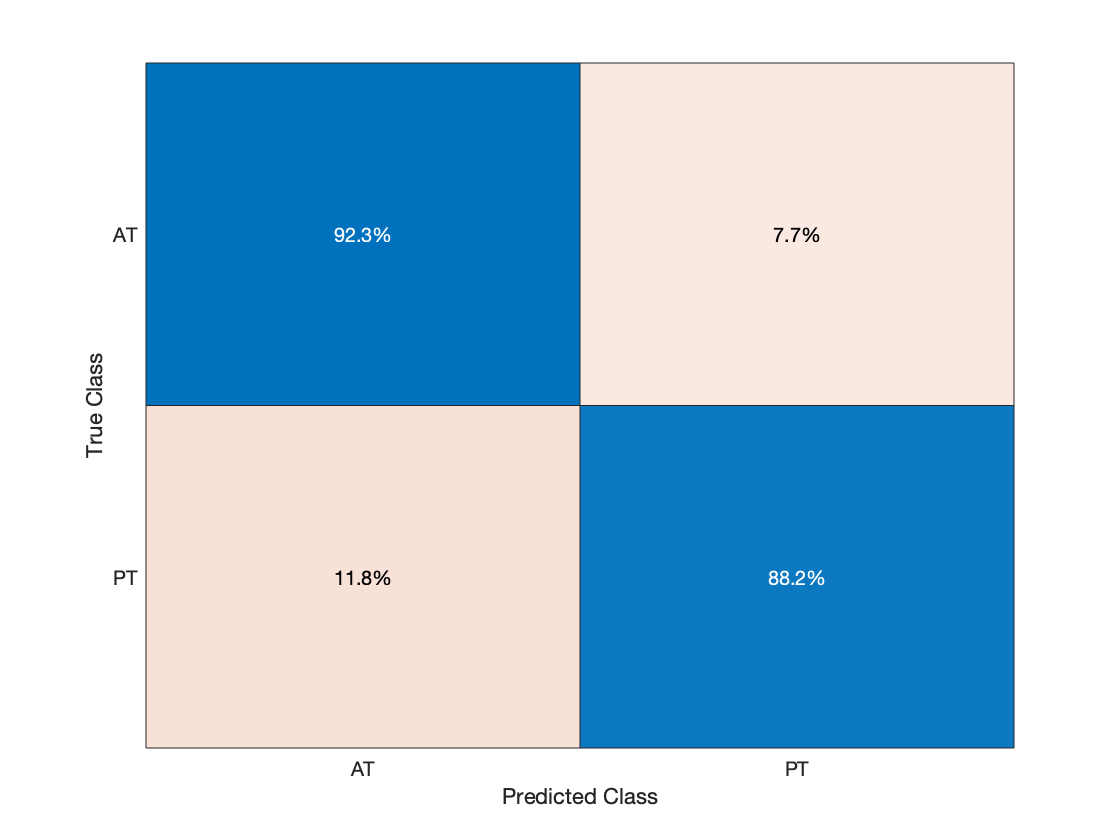

Error using perfcurve>membership (line 705)
Positive class is not found in the input data.

Error in perfcurve (line 449)
[W,subYnames] = membership(cls(sorted),weights(sorted),...

Error in trainClassifier (<a hre

[trainedClassifier, validationAccuracy] = trainClassifier(Dataset,Kernel,KernelScale);

fprintf('The Trainig accuracy is %.1f%% \n',validationAccuracy*100);

%opt.format = 'pdf'
%opt.showCode = false;
%opt.outputDir = "/Users/lucagarello/Desktop/"
%publish('Classifier.mlx',opt)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% NEW DATA FOR AT/PT CLASSIFICATION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% jan = readmatrix('PT(jan).csv');
% %% Table creation  
% Table = array2table(jan);
% % Labels
% Labls(1:size(jan,1),1) = {'POS'};
% %Append the labels to the matrix containing the parameters
% Table(:,size(Table,2)+1) = Labls;
% varNames = {'VelHandsCorrelation','AccHandsCorrelation','JerkHandsCorrelation','VelFeetCorrelation','AccFeetCorrelation','JerkFeetCorrelation'...
% 'skew_Nose','skew_hands','skew_feet','Area_Nose','Area_Hands','Area_Feet','AreaStd_Nose','AreaStd_Hands','AreaStd_Feet', ...
% 'Periodicity_Nose','Periodicity_Hands','Periodicity_Feet','Labels'};
% Table.Properties.VariableNames = varNames ;
% % 
% Dataset = [Dataset ; Table];
% find_outliers2(Dataset,0);
%Dataset(7,:) = [];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%